# EL6023 Final Project

## Initial Stuff, RX TX Positions, Gains, URA  platform

Loading Data

load roomPathData.mat

Creating antenna element, boresight in positive x-axis

fc = pathData.fc;
elem = design(patchMicrostrip, fc);
elem.Tilt = 90;
elem.TiltAxis = [0 1 0];


Antenna platforms

nantgNB = [4,4];
nantUE = 8;

lambda = physconst('LightSpeed')/fc;
dstep = lambda/2;

arrgNB = phased.URA(nantgNB,dstep,"ArrayNormal","x");
arrUE = phased.ULA(nantUE,dstep,"ArrayAxis","x");

arrPlatformgNB = ArrayPlatform('elem', elem, 'arr', arrgNB, 'fc', fc);
arrPlatformgNB.computeNormMatrix();

arrPlatformUE =  ArrayPlatform('elem', elem, 'arr', arrUE, 'fc', fc);
arrPlatformUE.computeNormMatrix();

Paths, gains, delay, angles

txPos = pathData.txPos;
rxNum = 15;
rxPos = pathData.rxPos(rxNum,:);



txPow = 15; %dB
nf = 7;      % Noise figure
bw = 400e6;  % Bandwidth
Ekt = -174;  % Thermal noise



%Path Stuff
npaths = pathData.npaths(rxNum,:);
pl = pathData.pl(rxNum,:);
gain = txPow - pl'  - nf - Ekt - 10*log10(bw);
dly = pathData.dly(rxNum,:);

aoaAz = pathData.aoaAz(rxNum,:)';
aoaEl = pathData.aoaEl(rxNum,:)';
aodAz = pathData.aodAz(rxNum,:)';
aodEl = pathData.aodEl(rxNum,:)';

- Try LOS, NLOS, …

- Create a FD channel 

- Use the one from the previous lab

- Enter the parameters from that data

- Simulate an OFDM over a slot

## **OFDM CHANNEL**

SubcarrierSpacing = 120;    % SCS in kHZ
NRB = 61;  % number of resource blocks
nscPerRB = 12;  % number of sub-carriers per RB

carrierConfig = nrCarrierConfig(...
    'NSizeGrid', NRB, 'SubcarrierSpacing', SubcarrierSpacing);
waveformConfig = nrOFDMInfo(carrierConfig);

Enoise = -100;  % Energy per noise sample in dB
fdchan = FDMIMOChan(carrierConfig, 'txArrPlatform', arrPlatformgNB, 'rxArrPlatform', arrPlatformUE, ...
    'aoaAz', aoaAz, 'aodAz', aodAz, 'aoaEl', aoaEl, 'aodEl', aodEl,  ...
    'gain', gain, 'dly', dly, 'fc', fc, 'Enoise', Enoise);

frameNum = 0;
slotNum = 0;
[chanGrid, noiseVar] = fdchan.step(frameNum, slotNum);

- Or a few slots

- Estimate the TX side spatial covariance matrix

- The average of H’*H over times and freq

Calculating average of H'*H

Q = pagemtimes(permute(conj(chanGrid),[2 1 3 4]),chanGrid); %TAKES A WHILE DON'T RUN MULTIPLE TIMES AMRIT
Q = squeeze(mean(mean(Q,3),4));

- Select a TX pre-coder for some rank, nstream

- Apply that pre-coder to all RE

- So, now on each RE you will have a nrx x nstream matrix, G

Precoder

nstream = 2;
[V,D] = eig(Q);
Fprecoder = V(:,end-nstream+1:end);
G = pagemtimes(chanGrid,Fprecoder); %Pre-coded channel

- Look at the demo:

- https://www.mathworks.com/help/5g/ug/nr-pdsch-throughput.html

- Numlayers = number of streams

- Very similar to the FD PDSCH demo we did with HARQ

TX STUFF

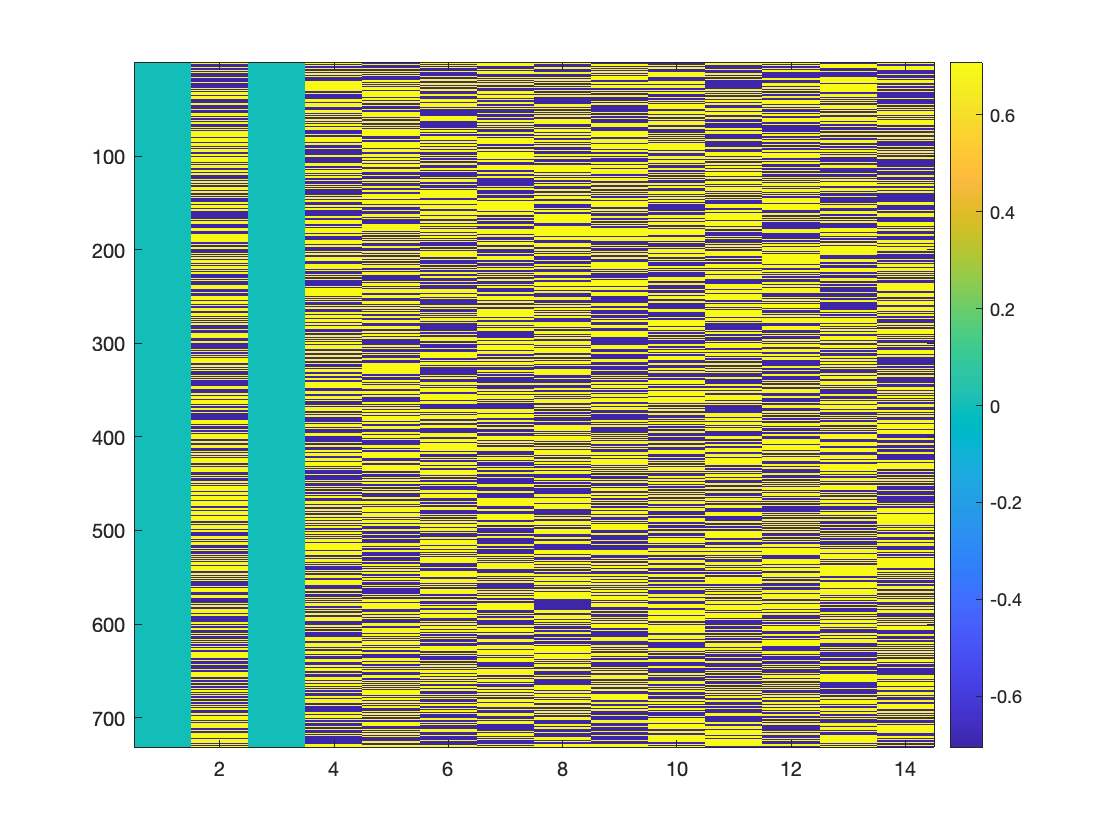

mcsInd = 1;

Modulation = 'QPSK';
targetCodeRate = 157/1024;

pdschConfig = nrPDSCHConfig(...
    'Modulation', Modulation, ...
    'PRBSet', (0:NRB-1), ...
    'SymbolAllocation', [1, waveformConfig.SymbolsPerSlot-1], ...
    'PTRS', nrPDSCHPTRSConfig(),...
    'NumLayers', nstream);
  %  'EnablePTRS', 1,...
tx = NRgNBTxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate, 'nant',16);

txgrid = tx.step(Fprecoder);

imagesc(real(txgrid(:,:,1)))
colorbar

txgrid = permute(txgrid,[3,1,2]);
txgrid = reshape(txgrid,[nstream,1,732,14]);
txGridPrecoded = pagemtimes(Fprecoder,txgrid);

rxgrid = pagemtimes(chanGrid,txGridPrecoded);



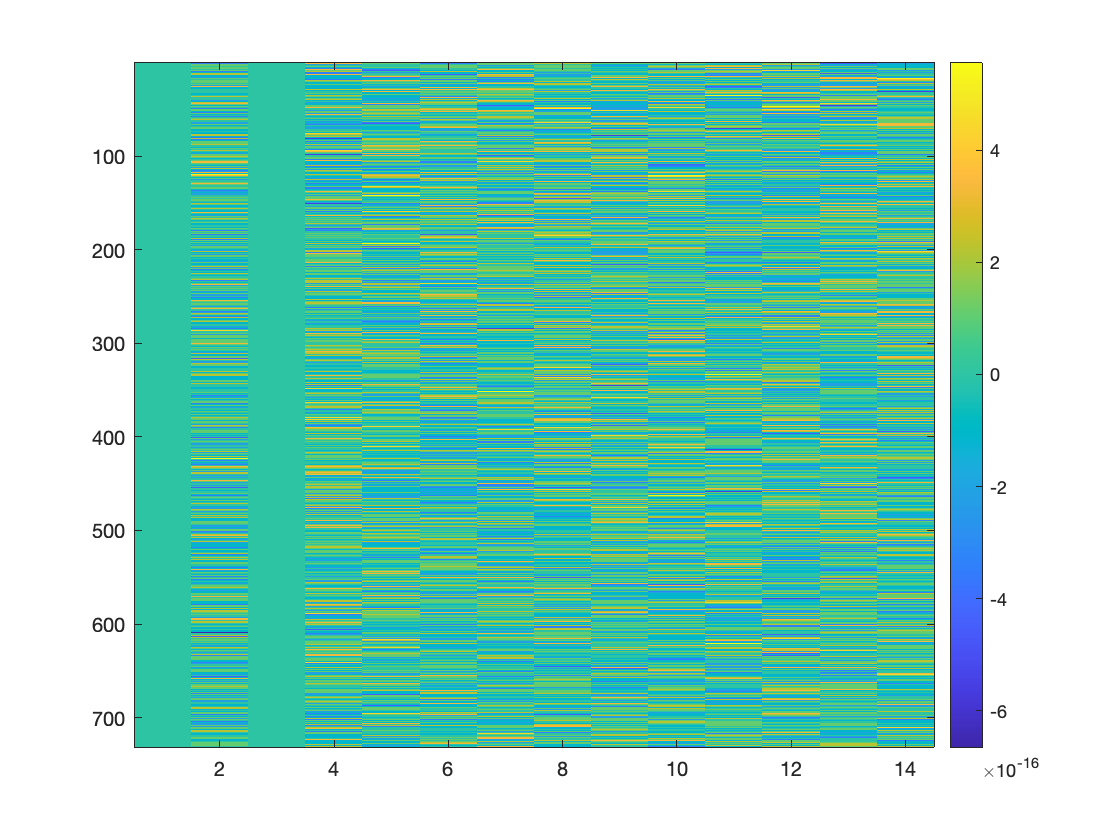

Gconj = permute(conj(G),[2,1,3,4]);
Flmmse = zeros(size(Gconj));
for i=1:732
    for j = 1:14
        Flmmse(:,:,i,j)=(Gconj(:,:,i,j)*G(:,:,i,j))^-1*Gconj(:,:,i,j);
    end
end

Hest = pagemtimes(Flmmse,G);
rxGridEq = squeeze(pagemtimes(Flmmse,rxgrid));
imagesc(real(squeeze(rxGridEq(1,:,:)))-squeeze(real(txgrid(1,1,:,:))))
colorbar


rx = NRUERxFD(carrierConfig, pdschConfig, 'targetCodeRate', targetCodeRate);
rx.step(rxGridEq, Hest, 0);

%Test
txBits1 = tx.txBits{1};
rxBits1 = rx.rxBits;

% txBits2 = tx.txBits{2};
% rxBits2 = rx.rxBits{2};

A1 = length(find(rx.rxBits == tx.txBits{1}));
% A2 = length(find(rx.rxBits{2} == tx.txBits{2}));

L1 = length(tx.txBits{1});
% L2 = length(tx.txBits{2});
%fprintf('Total bits %d and Correct bits %d',length(tx.txBits{1}),length(find(rx.rxBits{1} == tx.txBits{1})))

fprintf('%d,%d',A1,L1)

2718,5384

RECEIVER (I THINK)

%Now we multiply with chanGrid


- Use this to modify the PDSCH simulation we did to handle multiple streams

- You may need to implement the LMMSE decoder

- When you are done, you will be able to TX and RX coded across multiple streams

- Try a few different MCS and ranks until you get a throughput